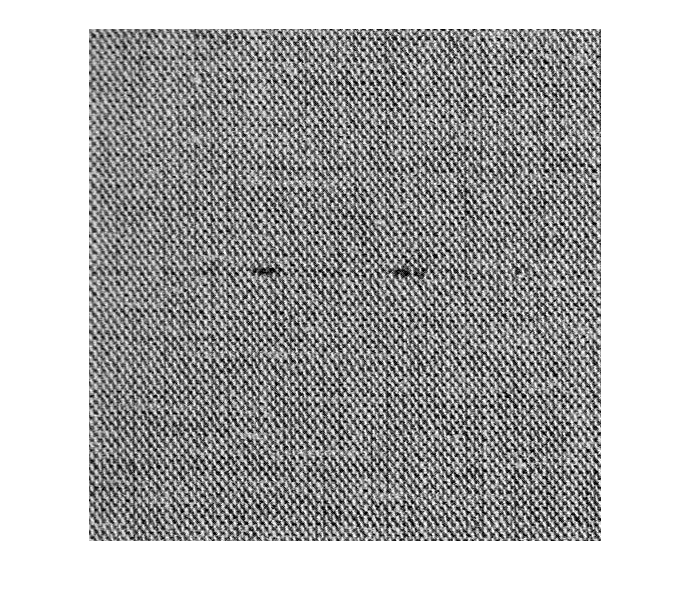

clear all
close all
clc

% Lettura immagini
B= rgb2gray(imread('i6.jpg'));

%Ricavo le dimensioni dell'immagine
[R,C]=size(B);

%% PREPROCESSING e RICERCA DELLA DIMENSIONE DEI PATTERN

%Aumento contrasto con imadjust con stretchlim che imposta automaticamente
%la soglia minima del contrasto
A = imadjust(B,stretchlim(B),[]);

figure;
imshow(A);



%Ricerca dei massimi  di correlazione con funzione graycoprops
offsets0 = [zeros(40,1) (1:40)'];
glcm = graycomatrix(A, 'offset', offsets0);
stats = graycoprops(glcm,'Contrast Correlation');

figure, plot([stats.Correlation]);
title('Texture Correlation as a function of offset');
xlabel('Horizontal Offset')
ylabel('Correlation')    

%Ricerca del numeri di massimi
Massimi = findpeaks(stats.Correlation);
if length(Massimi) < 3
    %Se i massimi sono meno di 3
    Massimi = Massimi(length(Massimi));
else
    %Pulizia dei massimi non rilevanti(i primi 2)
    Massimi = Massimi(3:length(Massimi));
end

%Massimi rilevanti ordinati in ordine decrescente
Massimi = sort(Massimi, 'descend');

%Prendo dal primo posto dell'array il valore corrispondente alla dimensione
%ottimale da utilizzare come pattern
maxValue = Massimi(1);

%Prendo la dimensione ottimale del pattern
patternDimension = find(stats.Correlation == maxValue);

% Definisco i pattern con la dim ottimale ricavata sopra
%Facciamo 10 pattern 
pattern1 = A(1 : patternDimension, 1 : patternDimension);                   %Alto a sinistra
pattern2 = A(R - patternDimension : R - 1, C - patternDimension : C - 1);   %Basso a destra
pattern3 = A(R - patternDimension : R - 1, 1 : patternDimension);           %Basso a sinistra
pattern4 = A(1 : patternDimension, C - patternDimension : C - 1);           %Alto a destra
pattern5 = A(2 : patternDimension + 1, 2 : patternDimension + 1);
pattern6 = A(R - patternDimension - 1 : R - 2, C - patternDimension - 1 : C - 2 );
pattern7 = A(R - patternDimension - 1 : R - 2, 2 : patternDimension + 1 );
pattern8 = A(2 : patternDimension + 1, C - patternDimension - 1 : C - 2);
pattern9 = A(3 : patternDimension + 2, 3 : patternDimension + 2);
pattern10= A(3 : patternDimension + 2, C - patternDimension - 2 : C - 3);

%% CROSS-CORRELAZIONE

% Calcolo la xcorr-2D (normalizzata) per ogni pattern.
c1 = normxcorr2(pattern1,A); 
c2 = normxcorr2(pattern2,A);
c3 = normxcorr2(pattern3,A);
c4 = normxcorr2(pattern4,A);
c5 = normxcorr2(pattern5,A);
c6 = normxcorr2(pattern6,A);
c7 = normxcorr2(pattern7,A);
c8 = normxcorr2(pattern8,A);
c9 = normxcorr2(pattern9,A);
c10= normxcorr2(pattern10,A);

% Calcolo la matrice di cross-correlazione media
c = (c1 + c2 + c3 + c4 + c5 + c6 + c7 + c8 + c9 + c10) / 10;
display(mean(abs(c),'all'));

    0.0692




%% POSTPROCESSING

% Parametrizzazione raggio del disk di strel
if mean(abs(c),'all') < 0.07
    sizeofdisk = 1;
else
    sizeofdisk = 2;
end

% Ritaglio dell'immagine per eliminare i bordi derivati dalla
% cross-correlazione
[altezza, larghezza] = size(c);
scarto = (altezza-500)/2;
scarto = cast(scarto,'int32');
if rem(altezza,2) ~= 0
    c = c(scarto:(end-scarto),scarto:(end-scarto));
else
    c = c(scarto:(end-(scarto+1)),scarto:(end-(scarto+1)));
end

c = abs(c);

c =     0.0056    0.0459    0.0627    0.0492    0.0105    0.0343    0.0531    0.0308    0.0231    0.0724    0.0874    0.0649    0.0179    0.0324    0.0543    0.0297    0.0251    0.0713    0.0858    0.0682    0.0242    0.0265    0.0476    0.0174    0.0402    0.0832    0.0911    0.0659    0.0169    0.0331    0.0485    0.0166    0.0385    0.0766    0.0811    0.0551    0.0020    0.0461    0.0453    0.0029    0.0588    0.0867    0.0762    0.0370    0.0157    0.0528    0.0441    0.0063    0.0610    0.0856
    0.0085    0.0205    0.0402    0.0437    0.0228    0.0158    0.0430    0.0385    0.0029    0.0367    0.0614    0.0621    0.0357    0.0087    0.0430    0.0405    0.0054    0.0332    0.0592    0.0663    0.0445    0.0018    0.0369    0.0292    0.0109    0.0495    0.0693    0.0651    0.0310    0.0191    0.0497    0.0345    0.0083    0.0439    0.0601    0.0552    0.0193    0.0309    0.0462    0.0146    0.0304    0.0575    0.0629    0.0428    0.0026    0.0461    0.0512    0.0143    0.0306    0


% Calcolo della threshold e creo la nuova maschera
lv = graythresh(c);
maskt = c > (lv);
display(size(maskt));

   500   500



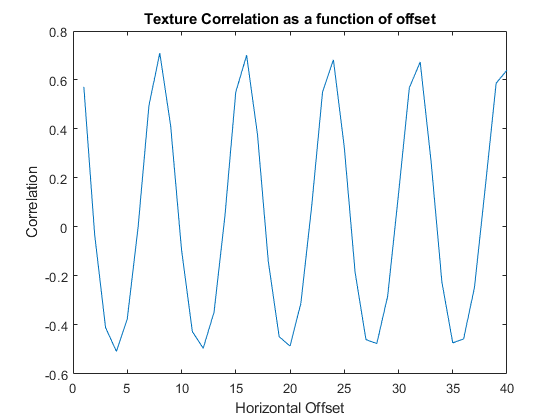

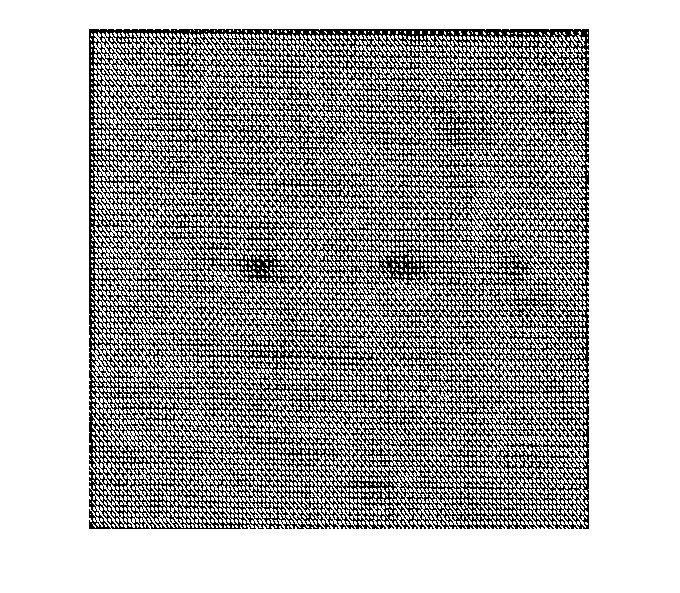

figure; 
imshow(maskt);

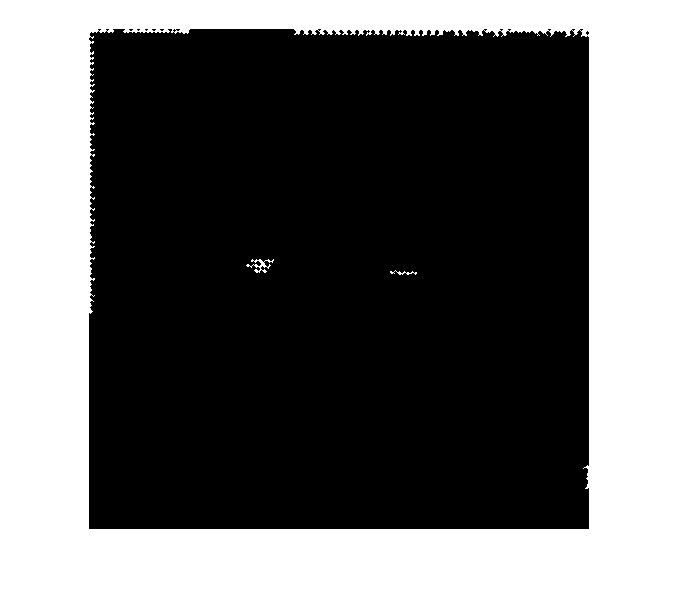


% Erosione dettagli non rilevanti cioè che non corrispondono ai difetti
se3 = strel("disk", sizeofdisk);
maskt = imdilate(maskt, se3);
maskt = imcomplement(maskt);

% Ricerca delle componenti connesse più grandi
CC = bwconncomp(maskt);
maskt = bwareafilt(maskt,CC.Connectivity,'largest');
imshow(maskt);

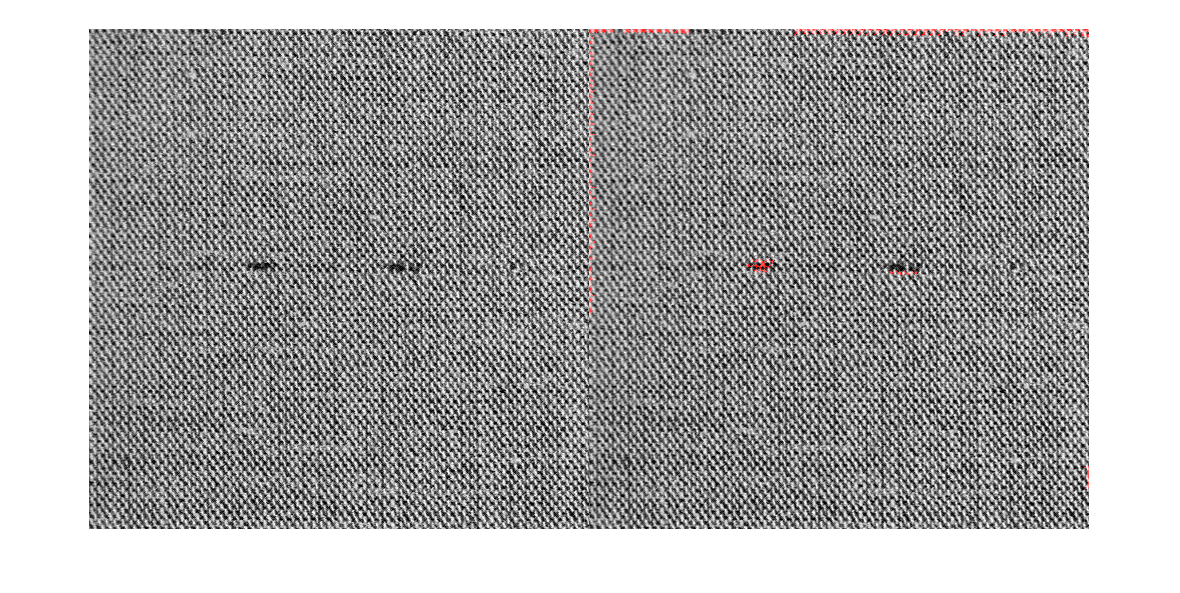


% Evidenziazione dell'errore nell'immagine di partenza
A=A(6:end-7,6:end-7);  % Passo da 512x512 a 500x500
A1 = A;
A1(maskt)=255;

%Confronto l'immagine iniziale con quella che mette in evidenza l'errore
Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')